clear all;
opts = detectImportOptions('Multipath fading traces (10x50 traces).xlsx')

opts =   SpreadsheetImportOptions with properties:

   Sheet Properties:
                        Sheet: ''

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 47 more}
                VariableTypes: {'double', 'double', 'double' ... and 47 more}
        SelectedVariableNames: {'Var1', 'Var2', 'Var3' ... and 47 more}
              VariableOptions: Show all 50 VariableOptions 
	Access Vari

preview('Multipath fading traces (10x50 traces).xlsx',opts)

ans = 8×50 table
     Var1       Var2       Var3        Var4        Var5       Var6       Var7       Var8       Var9       Var10      Var11      Var12      Var13      Var14      Var15     Var16     Var17      Var18      Var19     Var20      Var21      Var22       Var23      Var24      Var25      Var26      Var27      Var28      Var29      Var30      Var31      Var32       Var33      Var34       Var35  

## readmatrix

for sheetcount = 1:10

opts.Sheet = sheetcount;
 
MFE = readmatrix('Multipath fading traces (10x50 traces).xlsx',opts);


ISD = 1;
R = ISD/2;

Signal_transmitted = 1000*20/50;

for j=1:50 %PRB loop 50
A=MFE(:,j);

 %user0

S_received = pow2db(Signal_transmitted)+pathgain(R/10*sheetcount)+A;

interference_mpf=zeros(5000,36);

for b=1:36 %cell loop
B=circshift(A,5000-135*b);
interference_mpf(:,b)=B;
end
%calculation for interference

for i = 1:36
    if i <=6
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(ISD)+interference_mpf(:,i);
    elseif i<=18 && i>6
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(2*ISD)+interference_mpf(:,i);     
    elseif i>=19
        interference_tier(:,i) = pow2db(Signal_transmitted)+pathgain(3*ISD)+interference_mpf(:,i);
    end
end
interference_tier = db2pow(interference_tier);
interference = sum(interference_tier,2);

N = 1.3806488*10^(-23)*290*180000*1000; %mW
SINR=db2pow(S_received)./ ((interference)+db2pow(N));
SINRw(:,j) = SINR
SINRdb(:,j) = pow2db(SINR);

end

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

B = 180000

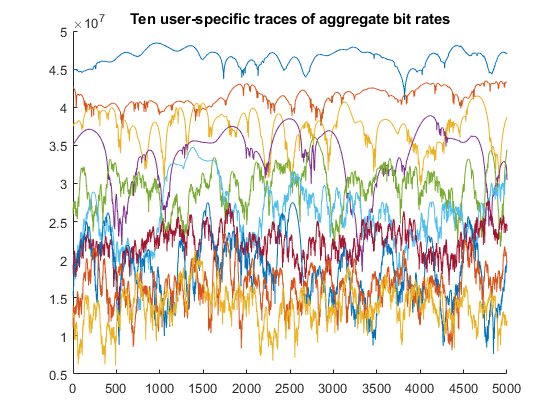

B = 0.18 %MHz


x = 1:5000;
for i = 1:50
    %% shannon formula
    Bit_rate(:,i,sheetcount) = real(B*log2(1+SINRw(:,i)));
end
Y = Bit_rate(:,:,sheetcount)';
Aggregate_Y(sheetcount,:) = sum(Y);
hold on;
plot(Aggregate_Y(sheetcount,:))
title('Ten user-specific traces of aggregate bit rates')
end

Time_average = mean(Aggregate_Y')

Time_average = 	1.0e+07 *

    4.6477    4.1339    3.7340    3.3627    2.9671    2.6225    2.2391    1.8726    1.6697    1.3997


save('Aggregate_bitrate.mat','Aggregate_Y','Bit_rate')